#  OFDMA System Design.

## Basic system+16Qam+2 Users+Channel Estimation

### Variables:

clear all
close all
clc
Bits =16;
% Symbols = [1,-1];
R = 10^4;
y_c1 = zeros(1,19);
y_c2 = zeros(1,19);
N = 16; % # subcarriers
L = 4;  % # channel taps
cpn = 3;% number of symbols involved with cyclic prefix

### **SNR Initialization:**

SNR_dB = 0:0.5:20;
SNR_linear = 10.^(SNR_dB./10);
for si = 1: length(SNR_linear)
    SNR_samp = SNR_linear(si);
    variance = 10./SNR_samp;

    for ri = 1:R

## ---TRANSMITTER---

### Generating Symbols:

- Generating 16 symbols from a 64 bits bit stream. 

- The maping is as follows:

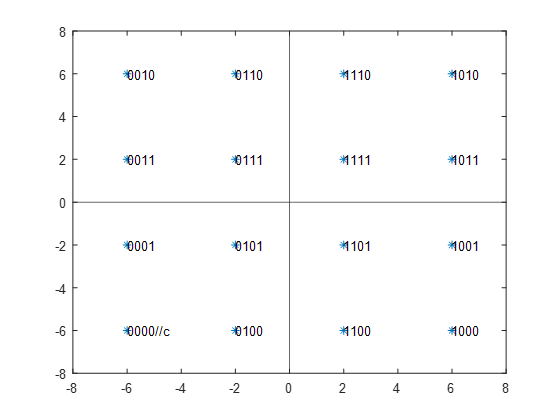

- Code to generate the above Plot.

- Bit allocation:

$\left\lbrack \begin{array}{ccccccc}
0 & 0 & 0 & 0 & = & -6 & +6i\\
0 & 0 & 0 & 1 & = & -6 & +2i\\
0 & 0 & 1 & 0 & = & -6 & -6i\\
0 & 0 & 1 & 1 & = & -6 & -2i\\
0 & 1 & 0 & 0 & = & -2 & +6i\\
0 & 1 & 0 & 1 & = & -2 & +2i\\
0 & 1 & 1 & 0 & = & -2 & -6i\\
0 & 1 & 1 & 1 & = & -2 & -2i
\end{array}\right\rbrack$& $\left\lbrack \begin{array}{ccccccc}
1 & 0 & 0 & 0 & = & 6 & +6i\\
1 & 0 & 0 & 1 & = & 6 & +2i\\
1 & 0 & 1 & 0 & = & 6 & -6i\\
1 & 0 & 1 & 1 & = & 6 & -2i\\
1 & 1 & 0 & 0 & = & 2 & +6i\\
1 & 1 & 0 & 1 & = & 2 & +2i\\
1 & 1 & 1 & 0 & = & 2 & -6i\\
1 & 1 & 1 & 1 & = & 2 & -2i
\end{array}\right\rbrack$

- The Pilot bits for User 1  are assigned to positions, 1,3,5,8,17,19,21,24,33,35,37,40,49,51,53,56. and are mapped to the symbol 6+6i.

$\left\lbrack \begin{array}{ccccccc}
1 & 0 & 0 & 0 & = & 6 & +6i\\
\textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & = &  & \textrm{infoSym}\\
1 & 0 & 0 & 0 & = & 6 & +6i\\
\textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & = &  & \textrm{infoSym}\\
1 & 0 & 0 & 0 & = & 6 & 6i\\
\textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & = &  & \textrm{infoSym}\\
\textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & = &  & \textrm{infoSym}\\
1 & 0 & 0 & 0 & = & 6 & 6i
\end{array}\right\rbrack$& $\left\lbrack \begin{array}{ccccccc}
\textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & = &  & \textrm{infoSym}\\
\textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & = &  & \textrm{infoSym}\\
\textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & = &  & \textrm{infoSym}\\
\textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & = &  & \textrm{infoSym}\\
\textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & = &  & \textrm{infoSym}\\
\textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & = &  & \textrm{infoSym}\\
\textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & = &  & \textrm{infoSym}\\
\textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & = &  & \textrm{infoSym}
\end{array}\right\rbrack$

- The Pilot bits for User 2  are assigned to positions, 9,11,13,16,25,27,29,32,41,43,45,57,59,61,64 and are mapped to the symbol 6+6i.

- $\left\lbrack \begin{array}{ccccccc}
\textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & = &  & \textrm{infoSym}\\
\textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & = &  & \textrm{infoSym}\\
\textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & = &  & \textrm{infoSym}\\
\textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & = &  & \textrm{infoSym}\\
\textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & = &  & \textrm{infoSym}\\
\textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & = &  & \textrm{infoSym}\\
\textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & = &  & \textrm{infoSym}\\
\textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & = &  & \textrm{infoSym}
\end{array}\right\rbrack$&$\left\lbrack \begin{array}{ccccccc}
1 & 0 & 0 & 0 & = & 6 & +6i\\
\textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & = &  & \textrm{infoSym}\\
1 & 0 & 0 & 0 & = & 6 & +6i\\
\textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & = &  & \textrm{infoSym}\\
1 & 0 & 0 & 0 & = & 6 & 6i\\
\textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & = &  & \textrm{infoSym}\\
\textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & \textrm{infoBit} & = &  & \textrm{infoSym}\\
1 & 0 & 0 & 0 & = & 6 & 6i
\end{array}\right\rbrack$

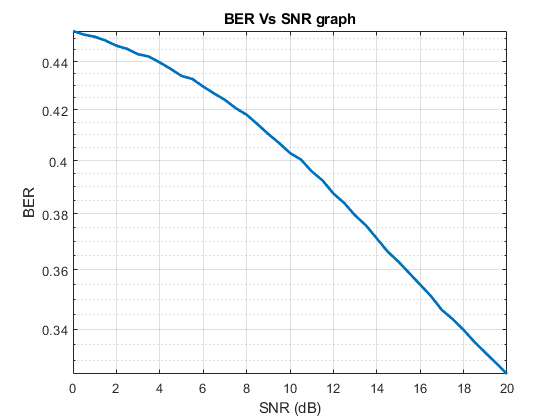

        ConstPts1 = [-6-6*j -2-6*j 6-6*j 2-6*j -6-2*j -2-2*j 6-2*j 2-2*j -6+6*j -2+6*j 6+6*j 2+6*j -6+2*j -2+2*j 6+2*j 2+2*j];
        BitStream1 = randi(2,1,4*16) - 1;
        bits1_2 = reshape(BitStream1, 16, 4);
        bits1_2(1)=1;
        bits1_2(3)=1;

        bits1_2(5)=1;
        %         bits1_2(12)=1;
        bits1_2(8)=1;
        bits1_2(17)=0;
        bits1_2(19)=0;
        bits1_2(21)=0;
        %         bits1_2(28)=0;
        bits1_2(24)=0;
        bits1_2(33)=0;
        bits1_2(35)=0;
        bits1_2(37)=0;
        %         bits1_2(44)=0;
        bits1_2(40)=0;
        bits1_2(49)=0;
        bits1_2(51)=0;
        bits1_2(53)=0;
        %         bits1_2(60)=0;
        bits1_2(56)=0;

       for i=1:16
            [ae] = bits1_2(i,:);
            if (ae(1) == 0 & ae(2) == 0)
                x_re1(i) = -6;
            end
            if (ae(1) == 0 & ae(2) == 1)
                x_re1(i) = -2;
            end
            if (ae(1) == 1 & ae(2) == 1)
                x_re1(i) = 2;
            end
            if (ae(1) == 1 & ae(2) == 0)
                x_re1(i) = 6;
            end
            if (ae(3) == 0 & ae(4) == 0)
                x_im1(i) = 6;
            end
            if (ae(3) == 0 & ae(4) == 1)
                x_im1(i) = 2;
            end
            if (ae(3) == 1 & ae(4) == 1)
                x_im1(i) = -2;
            end
            if (ae(3) == 1 & ae(4) == 0)
                x_im1(i) = -6;
            end
            UE1(i) =  x_re1(i) + 1i*x_im1(i);
       end


        ConstPts2 =[-6-6*j -2-6*j 6-6*j 2-6*j -6-2*j -2-2*j 6-2*j 2-2*j -6+6*j -2+6*j 6+6*j 2+6*j -6+2*j -2+2*j 6+2*j 2+2*j];
        BitStream2 = randi(2,1,4*16) - 1;
        bits2_2 = reshape(BitStream2, 16, 4);
        bits2_2(9)=1;
        bits2_2(11)=1;
        bits2_2(13)=1;
        %         bits2_2(12)=1;
        bits2_2(16)=1;
        bits2_2(25)=0;
        bits2_2(27)=0;
        bits2_2(29)=0;
        %         bits2_2(28)=0;
        bits2_2(32)=0;
        bits2_2(41)=0;
        bits2_2(43)=0;
        bits2_2(45)=0;
        %         bits2_2(44)=0;
        bits2_2(57)=0;
        bits2_2(59)=0;
        bits2_2(61)=0;
        bits2_2(61)=0;
        %         bits2_2(60)=0;
        bits2_2(64)=0;

        for i=1:16
            [ae2] = bits2_2(i,:);
            if (ae2(1) == 0 & ae2(2) == 0)
                x_re2(i) = -6;
            end
            if (ae2(1) == 0 & ae2(2) == 1)
                x_re2(i) = -2;
            end
            if (ae2(1) == 1 & ae2(2) == 1)
                x_re2(i) = 2;
            end
            if (ae2(1) == 1 & ae2(2) == 0)
                x_re2(i) = 6;
            end
            if (ae2(3) == 0 & ae2(4) == 0)
                x_im2(i) = 6;
            end
            if (ae2(3) == 0 & ae2(4) == 1)
                x_im2(i) = 2;
            end
            if (ae2(3) == 1 & ae2(4) == 1)
                x_im2(i) = -2;
            end
            if (ae2(3) == 1 & ae2(4) == 0)
                x_im2(i) = -6;
            end
            UE2(i) =  x_re2(i) + 1i*x_im2(i);
        end


### Interleaving:

- Generated Symbols are interleaved, so that when the infrmation is split to two users at the reciver, they get their desired bits. 

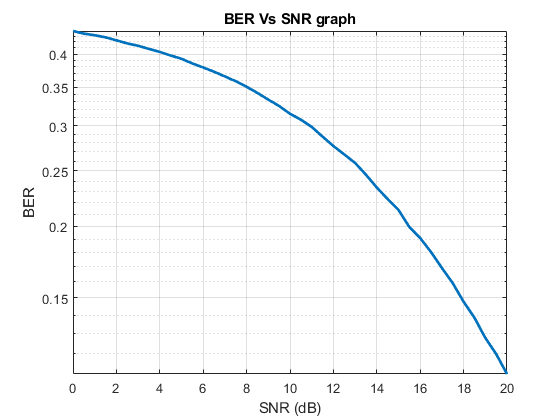

        xiv1 = UE1';
        xiv2 = UE2';
        xx = reshape([xiv1(:) xiv2(:)]',2*size(xiv1,1), [])';%32
        OFDM1 = xx(1:16);%16
        OFDM2 = xx(17:32);%16

### Applying IDFT:

- Now we perform IDFT from the function that I created, and no the inbuilt function.

        x1_idft = myidft(OFDM1);
        x2_idft = myidft(OFDM2);



### Adding Cyclic Prefix

- Next, we add cyclic prefix, i.e the last three symbols are repeated to the front.

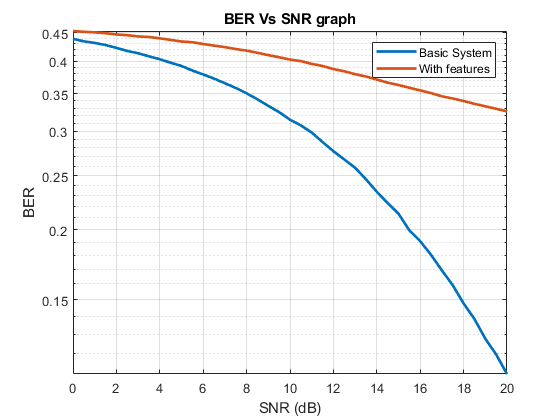

        for cpi=1:3
            xx1(cpi) =[x1_idft(N-cpn+cpi)];
            xx2(cpi) =[x2_idft(N-cpn+cpi)];
        end

        xcp1 = [xx1 x1_idft];
        xcp2 = [xx2 x2_idft];

### Generating Channels:

        for ci = 1:4
            h1(ci) = sqrt(0.25/2)*(randn(1) + 1i*randn(1));
            h2(ci) = sqrt(0.25/2)*(randn(1) + 1i*randn(1));
        end

### Generating Noise:

        for k = 1:19
            w1(k) = sqrt(variance/2)*(randn(1) + 1i*randn(1));
            w2(k) = sqrt(variance/2)*(randn(1) + 1i*randn(1));
        end

### ---RECIVER---

### Input at Reciver:

- The channeles are Convoluted with the symbols and recived at the reciver with added noise.

        y_c1(1) = h1(1)*xcp1(1) + w1(1);
        y_c1(2) = h1(1)*xcp1(2) + h1(2)*xcp1(1) + w1(2);
        y_c1(3) = h1(1)*xcp1(3) + h1(2)*xcp1(2) + h1(3)*xcp1(1) + w1(3);
        for k = 4:19
            y_c1(k) = h1(1)*xcp1(k) + h1(2)*xcp1(k-1) + h1(3)*xcp1(k-2) + h1(4)*xcp1(k-3) + w1(k);
        end

        y_c2(1) = h2(1)*xcp2(1) + w2(1);
        y_c2(2) = h2(1)*xcp2(2) + h2(2)*xcp2(1) + w2(2);
        y_c2(3) = h2(1)*xcp2(3) + h2(2)*xcp2(2) + h2(3)*xcp2(1) + w2(3);
        for k = 4:19
            y_c2(k) = h2(1)*xcp2(k) + h2(2)*xcp2(k-1) + h2(3)*xcp2(k-2) + h2(4)*xcp2(k-3) + w2(k);
        end

### Removing Cyclic Prefix:

        y1 = y_c1((cpn+1):length(y_c1));
        y2 = y_c2((cpn+1):length(y_c2));

### Applying DFT:

- Now we perform DFT from the function that I created, and no the inbuilt function.

        y1_dft = mydft(y1);
        y2_dft = mydft(y2);

### Generating Gk:

- Channel estimation is performend by using Maximum likelyhood function:

- The $Z_{4\textrm{x4}\;}$matrx is found by $\left\lbrack \begin{array}{c}
{\textrm{Uk}}_{1\textrm{x4}} \textrm{D1}\\
{\textrm{Uk}}_{1\textrm{x4}} \textrm{D2}\\
{\textrm{Uk}}_{1\textrm{x4}} \textrm{D3}\\
{\textrm{Uk}}_{1\textrm{x4}} \textrm{D4}
\end{array}\right\rbrack$

- Then find the estimated chnnel by using this formula ${\hat{h} }_{4\textrm{x1}} ={\left(Z_{4\textrm{x4}}^* Z_{4\textrm{x4}} \right)}^2$${Z^* }_{4\textrm{x4}}$$Y_{4\textrm{x1}}$

- Once the estimated channel is found, we use it that information to find $\hat{G_k } =\sum_n^{L-1} e^{-\textrm{j2}\pi \frac{\textrm{kn}}{N}} \hat{h_n }$

       
        z11 = [exp((-1i*2*pi)*((1-1)*(0))/(N)) exp((-1i*2*pi)*((1-1)*(1))/(N)) exp((-1i*2*pi)*((1-1)*(2))/(N)) exp((-1i*2*pi)*((1-1)*(3))/(N))]*OFDM1(1);
        z12 = [exp((-1i*2*pi)*((5-1)*(0))/(N)) exp((-1i*2*pi)*((5-1)*(1))/(N)) exp((-1i*2*pi)*((5-1)*(2))/(N)) exp((-1i*2*pi)*((5-1)*(3))/(N))]*OFDM1(5);
        z13 = [exp((-1i*2*pi)*((9-1)*(0))/(N)) exp((-1i*2*pi)*((9-1)*(1))/(N)) exp((-1i*2*pi)*((9-1)*(2))/(N)) exp((-1i*2*pi)*((9-1)*(3))/(N))]*OFDM1(9);
        z14 = [exp((-1i*2*pi)*((15-1)*(0))/(N)) exp((-1i*2*pi)*((15-1)*(1))/(N)) exp((-1i*2*pi)*((15-1)*(2))/(N)) exp((-1i*2*pi)*((15-1)*(3))/(N))]*OFDM1(15);
       
        z1 = [z11;z12;z13;z14];
        hest1 =  inv(conj(z1)*z1)*conj(z1)*[y1_dft(1);y1_dft(5);y1_dft(9);y1_dft(15)];
      
        for k = 1:length(y1_dft)
            for n = 1:4
                gg1(n) = hest1(n) * exp((-1i*2*pi)*((k-1)*(n-1))/(N));
                G1(k) = sum(gg1);
            end
        end
        
        z21 = [exp((-1i*2*pi)*((2-1)*(0))/(N)) exp((-1i*2*pi)*((2-1)*(1))/(N)) exp((-1i*2*pi)*((2-1)*(2))/(N)) exp((-1i*2*pi)*((2-1)*(3))/(N))]*OFDM2(2);
        z22 = [exp((-1i*2*pi)*((6-1)*(0))/(N)) exp((-1i*2*pi)*((6-1)*(1))/(N)) exp((-1i*2*pi)*((6-1)*(2))/(N)) exp((-1i*2*pi)*((6-1)*(3))/(N))]*OFDM2(6);
        z23 = [exp((-1i*2*pi)*((10-1)*(0))/(N)) exp((-1i*2*pi)*((10-1)*(1))/(N)) exp((-1i*2*pi)*((10-1)*(2))/(N)) exp((-1i*2*pi)*((10-1)*(3))/(N))]*OFDM2(10);
        z24 = [exp((-1i*2*pi)*((16-1)*(0))/(N)) exp((-1i*2*pi)*((16-1)*(1))/(N)) exp((-1i*2*pi)*((16-1)*(2))/(N)) exp((-1i*2*pi)*((16-1)*(3))/(N))]*OFDM2(16);
       
        z2 = [z21;z22;z23;z24];
        hest2 =  inv(conj(z2)*z2)*conj(z2)*[y2_dft(2);y2_dft(6);y2_dft(10);y2_dft(16)];
       
        for k = 1:length(y1_dft)
            for n = 1:4
                gg2(n) = hest2(n) * exp((-1i*2*pi)*((k-1)*(n-1))/(N));
                G2(k) = sum(gg2);
            end
        end



### Decoding using minimum distance decoder:




        for di = 1:length(y1_dft)
            dd1 = zeros(1,16);
            for m = 1:16
                dd1(m) = abs((y1_dft(di) - G1(di)*ConstPts1(m))^2);
            end
            [a,b] = min(dd1);
             x1hatofdm(di) = ConstPts1(b);
        end

        for ddi = 1:length(y2_dft)
            dd2 = zeros(1,4);
            for mm = 1:16
                dd2(mm) = abs((y2_dft(ddi) - G2(ddi)*ConstPts2(mm))^2);
            end
            [c,d] = min(dd2);
             x2hatofdm(ddi) = ConstPts2(d);
        end

### Distributing interleaved subcarriers:    

- Getting back the respective symbols of User 1 and User 2. 

- The expected UE1 and UE2 symbols would look like:

        for k = 1:8
            x1hat(k)=[x1hatofdm(k*2-1)];
            x1hat(k+8)= [x2hatofdm(k*2-1)];
        end

        for k = 1:8
            x2hat(k)=[x1hatofdm(k*2)];
            x2hat(k+8)=[x2hatofdm(k*2)];
        end

### Error counting:

- First the Symbols are mapped back to the bits.

- Followed by which, the recived bits are compared with the actual bits and error is calculated.

        bits_hat1 = zeros(16,4);

        for index = 1:16
            x_hat_re(index)=real(x1hat(index));
            x_hat_im(index)=imag(x1hat(index));

            if x_hat_re(index) == -6
                bits_hat1(index,1) = 0;
                bits_hat1(index,2) = 0;
            end
            if x_hat_re(index) == -2
                bits_hat1(index,1) = 0;
                bits_hat1(index,2) = 1;
            end
            if x_hat_re(index) == 6
                bits_hat1(index,1) = 1;
                bits_hat1(index,2) = 0;
            end
            if x_hat_re(index) == 2
                bits_hat1(index,1) = 1;
                bits_hat1(index,2) = 1;
            end
            if x_hat_im(index) == 6
                bits_hat1(index,3) = 0;
                bits_hat1(index,4) = 0;
            end
            if x_hat_im(index) == 2
                bits_hat1(index,3) = 0;
                bits_hat1(index,4) = 1;
            end
            if x_hat_im(index) == -6
                bits_hat1(index,3) = 1;
                bits_hat1(index,4) = 0;
            end
            if x_hat_im(index) == -6
                bits_hat1(index,3) = 1;
                bits_hat1(index,4) = 1;
            end
        end

        bits_hat2 = zeros(16,4);

         for index = 1:16
            x_hat_re2(index)=real(x2hat(index));
            x_hat_im2(index)=imag(x2hat(index));

            if x_hat_re2(index) == -6
                bits_hat2(index,1) = 0;
                bits_hat2(index,2) = 0;
            end
            if x_hat_re2(index) == -2
                bits_hat2(index,1) = 0;
                bits_hat2(index,2) = 1;
            end
            if x_hat_re2(index) == 6
                bits_hat2(index,1) = 1;
                bits_hat2(index,2) = 0;
            end
            if x_hat_re2(index) == 2
                bits_hat2(index,1) = 1;
                bits_hat2(index,2) = 1;
            end
            if x_hat_im2(index) == 6
                bits_hat2(index,3) = 0;
                bits_hat2(index,4) = 0;
            end
            if x_hat_im2(index) == 2
                bits_hat2(index,3) = 0;
                bits_hat2(index,4) = 1;
            end
            if x_hat_im2(index) == -6
                bits_hat2(index,3) = 1;
                bits_hat2(index,4) = 0;
            end
            if x_hat_im2(index) == -2
                bits_hat2(index,3) = 1;
                bits_hat2(index,4) = 1;
            end
         end


        for ei = 1:4*16
            error1(ei) = bits1_2(ei) ~= bits_hat1(ei);
        end
        for eei = 1:4*16
            error2(eei) = bits2_2(eei) ~= bits_hat2(eei);
        end
        Terror1(ri) = sum(error1);

        Terror2(ri) = sum(error2);


    end
    finaltotalerror = sum(Terror1) + sum(Terror2);
    BER(si) = (finaltotalerror)/(R*N*4*2);
end

## ---PLOTTING---

semilogy(SNR_dB, BER, 'linewidth',2);
grid on;
xlabel('SNR (dB)');
ylabel('BER');
title('BER Vs SNR graph');

#  Final Project.

## Basic system.

### Variables:

% clear all
Bitsb =16;
Symbolsb = [1,-1];
Rb = 10^4;
y_c1b = zeros(1,19);
y_c2b = zeros(1,19);
Nb = 16; % # subcarriers
Lb= 4;  % # channel taps
cpnb = 3;% number of symbols involved with cyclic prefix

### **SNR Initialization:**

SNR_dBb = 0:0.5:20;
SNR_linearb = 10.^(SNR_dBb./10);
for sib = 1: length(SNR_linearb)
    SNR_sampb = SNR_linearb(sib);
    varianceb = 4./SNR_sampb;

    for rib = 1:Rb

## ---TRANSMITTER---

### Generating Symbols:

        ConstPts1b=randi([-1 ,1],1,Bitsb);
        ConstPts1b(~ConstPts1b)=-1;
        x1b=ConstPts1b;
        
        ConstPts2b=randi([-1 ,1],1,16);
        ConstPts2b(~ConstPts2b)=-1;
        x2b=ConstPts2b;

### Applying IDFT:

        x1_idftb = myidft(x1b);
        x2_idftb = myidft(x2b);

### Adding Cyclic Prefix

        for cpi=1:3
            xx1b(cpi) =[x1_idftb(Nb-cpnb+cpi)];
            xx2b(cpi) =[x2_idftb(Nb-cpnb+cpi)];
        end
        xcp1b = [xx1b x1_idftb];
        xcp2b = [xx2b x2_idftb];

### Generating Channels:

        for cib = 1:4
            h1b(cib) = sqrt(0.25/2)*(randn(1) + 1i*randn(1));
            h2b(cib) = sqrt(0.25/2)*(randn(1) + 1i*randn(1));
        end

### Generating Noise:

        for kb = 1:19
            w1b(kb) = sqrt(varianceb/2)*(randn(1) + 1i*randn(1));
            w2b(kb) = sqrt(varianceb/2)*(randn(1) + 1i*randn(1));
        end

### Output at Transmiter:

        y_c1b(1) = h1b(1)*xcp1b(1) + w1b(1);
        y_c1b(2) = h1b(1)*xcp1b(2) + h1b(2)*xcp1b(1) + w1b(2);
        y_c1b(3) = h1b(1)*xcp1b(3) + h1b(2)*xcp1b(2) + h1b(3)*xcp1b(1) + w1b(3);
        for kb = 4:19
            y_c1b(kb) = h1b(1)*xcp1b(kb) + h1b(2)*xcp1b(kb-1) + h1b(3)*xcp1b(kb-2) + h1b(4)*xcp1b(kb-3) + w1b(kb);
        end

        y_c2b(1) = h2b(1)*xcp2b(1) + w2b(1);
        y_c2b(2) = h2b(1)*xcp2b(2) + h2b(2)*xcp2b(1) + w2b(2);
        y_c2b(3) = h2b(1)*xcp2b(3) + h2b(2)*xcp2b(2) + h2b(3)*xcp2b(1) + w2b(3);
        for kb = 4:19
            y_c2b(kb) = h2b(1)*xcp2b(kb) + h2b(2)*xcp2b(kb-1) + h2b(3)*xcp2b(kb-2) + h2b(4)*xcp2b(kb-3) + w2b(kb);
        end

## ---RECIVER---

### Removing Cyclic Prefix:

        y1b = y_c1b((cpnb+1):length(y_c1b));
        y2b = y_c2b((cpnb+1):length(y_c2b));

### Applying DFT:

        y1_dftb = mydft(y1b);
        y2_dftb = mydft(y2b);

### Generating Gk:

        for kb = 1:length(y1_dftb)
            for nb = 1:4
                gg1b(nb) = h1b(nb) * exp((-1i*2*pi)*((kb-1)*(nb-1))/(Nb));
                G1b(kb) = sum(gg1b);
            end
        end
        
        for kb = 1:length(y2_dftb)
            for nb = 1:4
                gg2b(nb) = h2b(nb) * exp((-1i*2*pi)*((kb-1)*(nb-1))/(Nb));
                G2b(kb) = sum(gg2b);
            end
        end

### Decoding using minimum distance decoder:

        for dib = 1:length(y1_dftb)
            dd1b = zeros(1,2);
            for mb = 1:2
                dd1b(mb) = abs((y1_dftb(dib) - G1b(dib)*Symbolsb(mb))^2);
            end
            [ab,bb] = min(dd1b);
            x1hatb(dib) = Symbolsb(bb);
        end
        
        for ddib = 1:length(y2_dftb)
            dd2b = zeros(1,2);
            for mmb = 1:2
                dd2b(mmb) = abs((y2_dftb(ddib) - G2b(ddib)*Symbolsb(mmb))^2);
            end
            [cb,db] = min(dd2b);
            x2hatb(ddib) = Symbolsb(db);
        end

### Error counting:

        for eib = 1:length(x1hatb)
            error1b(eib) = x1b(eib) ~= x1hatb(eib);
        end
        for eeib = 1:length(x2hatb)
            error2b(eeib) = x2b(eeib) ~= x2hatb(eeib);
        end
        Terror1b(rib) = sum(error1b);
        
        Terror2b(rib) = sum(error2b);

        
    end
    finaltotalerrorb = sum(Terror1b) + sum(Terror2b);
    BERb(sib) = (finaltotalerrorb)/(Rb*Nb*2);

end

## ---PLOTTING---

semilogy(SNR_dBb, BERb, 'linewidth',2);
grid on;
xlabel('SNR (dB)');
ylabel('BER');
title('BER Vs SNR graph')


semilogy(SNR_dB, BERb, 'linewidth',2);
hold on
grid on;
semilogy(SNR_dB, BER, 'linewidth',2);

xlabel('SNR (dB)');
ylabel('BER');
title('BER Vs SNR graph');
legend({'Basic System','With features'})